%load data
confidence = load('..\analyzed\DM101_unsmoothed\group_accuracy.mat');
%this is from colorbrewer: http://colorbrewer2.org/#type=sequential&scheme=BuGn&n=3
addpath('D:\Documents\software\cbrewer') %for color
[cb] = cbrewer('qual','Set1',10,'pchip');

detection_confidence = load('..\analyzed\DM102_unsmoothed\group_accuracy_detection.mat');
detection_confidence = detection_confidence.group_accuracy_detection;
ss = find(~isnan(detection_confidence(1,:)));
detection_confidence = detection_confidence(:,ss);

discrimination_confidence = load('..\analyzed\DM102_unsmoothed\group_accuracy_discrimination.mat');
discrimination_confidence = discrimination_confidence.group_accuracy_discrimination(:,ss);
ss = find(~isnan(discrimination_confidence(1,:)));
discrimination_confidence = discrimination_confidence(:,ss);

tilt_confidence = load('..\analyzed\DM102_unsmoothed\group_accuracy_discrimination.mat');
tilt_confidence = tilt_confidence.group_accuracy_discrimination(:,ss);
ss = find(~isnan(tilt_confidence(1,:)));
tilt_confidence = tilt_confidence(:,ss);

load('..\analyzed\DM105_unsmoothed\group_accuracy_YN.mat');
YN = group_accuracy_YN(:,ss);
ss = find(~isnan(YN(1,:)));
YN = YN(:,ss);

load('..\analyzed\DM105_unsmoothed\group_accuracy_CA.mat');
CA = group_accuracy_CA(:,ss);
ss = find(~isnan(CA(1,:)));
CA = CA(:,ss);

load('..\analyzed\DM105_unsmoothed\group_accuracy_TV.mat');
TV = group_accuracy_TV(:,ss);
ss = find(~isnan(TV(1,:)));
TV = TV(:,ss);

% detection_to_discrimination = load('..\analyzed\DM102_unsmoothed\group_accuracy_cross1.mat');
% detection_to_discrimination = detection_to_discrimination.group_accuracy_cross1(:,ss);
% 
% discrimination_to_detection = load('..\analyzed\DM102_unsmoothed\group_accuracy_cross2.mat');
% discrimination_to_detection = discrimination_to_detection.group_accuracy_cross2(:,ss);
% 
% YN_to_discrimination = load('..\analyzed\DM103_unsmoothed\group_accuracy_cross1.mat');
% YN_to_discrimination = YN_to_discrimination.group_accuracy_cross1(:,ss);
% 
% discrimination_to_YN = load('..\analyzed\DM103_unsmoothed\group_accuracy_cross2.mat');
% discrimination_to_YN=discrimination_to_YN.group_accuracy_cross2(:,ss);
% 
% YN = load('..\analyzed\DM103_unsmoothed\group_accuracy_YN.mat');
% YN = YN.group_accuracy_YN(:,ss);
% 
% dis_cross_det = mean(cat(3,discrimination_to_detection,detection_to_discrimination),3);
% dis_cross_YN = mean(cat(3,discrimination_to_YN,YN_to_discrimination),3);
% dis_mean_det = mean(cat(3,discrimination_confidence,detection_confidence),3);
% ROI_names = {'union FPl','union FPm','union 46','ventralStriatum',...
%     'vmPFC roi','precun roi','pMFC roi','ventricles roi'};


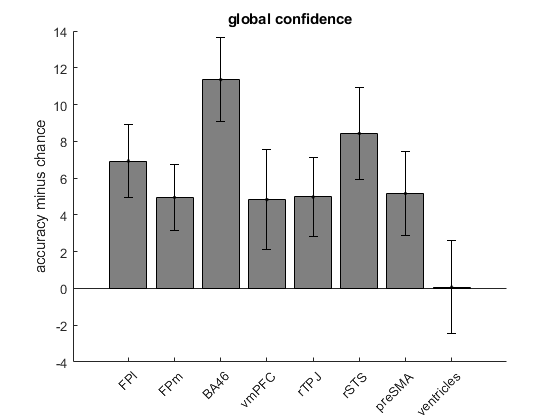

figure; hold on;
b_dis=bar(1:8,nanmean(confidence.group_accuracy,2),'FaceColor',[0.5,0.5,0.5]);
b_dis.FaceColor = 'flat';
% b_dis.CData(1:3,:) = 0.7*ones(3);
errorbar(1:8, nanmean(confidence.group_accuracy,2),nanstd(confidence.group_accuracy')/sqrt(29),'.k')
xticks(1:8);
xticklabels({'FPl','FPm','BA46','vmPFC','rTPJ','rSTS','preSMA', 'ventricles'});
xtickangle(45)
title('global confidence')
ylabel('accuracy minus chance')
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 20;
s.Height = 10;
hgexport(fig,'figures/confidence_classification',s);

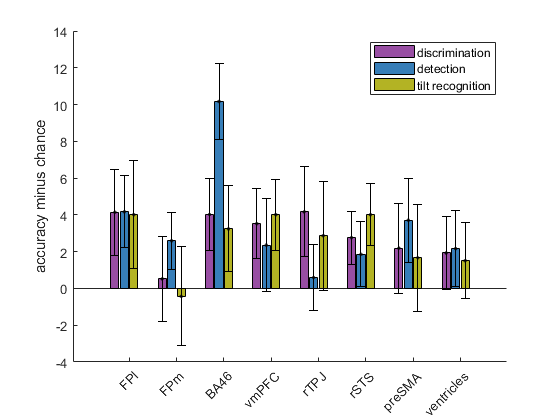

figure; hold on;

b_dis=bar(1:5:36,nanmean(discrimination_confidence,2),'FaceColor',cb(4,:),'BarWidth',0.17);
b_dis.FaceColor = 'flat';
errorbar(1:5:36, nanmean(discrimination_confidence,2),nanstd(discrimination_confidence')/sqrt(size(discrimination_confidence,2)),'.k')

b_det=bar(2:5:37,nanmean(detection_confidence,2),'FaceColor',cb(2,:),'BarWidth',0.17);
b_det.FaceColor = 'flat';
errorbar(2:5:37, nanmean(detection_confidence,2),nanstd(detection_confidence')/sqrt(size(detection_confidence,2)),'.k')

b_tilt=bar(3:5:38,nanmean(tilt_confidence,2),'FaceColor',cb(7,:)*0.7,'BarWidth',0.17);
b_tilt.FaceColor = 'flat';
errorbar(3:5:38, nanmean(tilt_confidence,2),nanstd(tilt_confidence')/sqrt(size(tilt_confidence,2)),'.k')

xticks(1.5+(1:5:36));
xticklabels({'FPl','FPm','BA46','vmPFC','rTPJ','rSTS','preSMA', 'ventricles'});
xtickangle(45)
ylabel('accuracy minus chance')
legend([b_dis,b_det,b_tilt],'discrimination','detection','tilt recognition')
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 25;
s.Height = 12;
hgexport(fig,'figures/confidence_by_task',s);

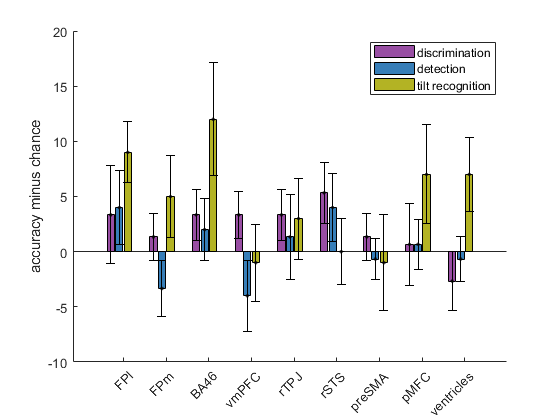

figure; hold on;

b_CA=bar(1:5:41,nanmean(CA,2),'FaceColor',cb(4,:),'BarWidth',0.17);
b_CA.FaceColor = 'flat';
errorbar(1:5:41, nanmean(CA,2),nanstd(CA')/sqrt(size(CA,2)),'.k')

b_YN=bar(2:5:42,nanmean(YN,2),'FaceColor',cb(2,:),'BarWidth',0.17);
b_YN.FaceColor = 'flat';
errorbar(2:5:42, nanmean(YN,2),nanstd(YN')/sqrt(size(YN,2)),'.k')

b_TV=bar(3:5:43,nanmean(TV,2),'FaceColor',cb(7,:)*0.7,'BarWidth',0.17);
b_TV.FaceColor = 'flat';
errorbar(3:5:43, nanmean(TV,2),nanstd(TV')/sqrt(size(TV,2)),'.k')

xticks(1.5+(1:5:41));
xticklabels({'FPl','FPm','BA46','vmPFC','rTPJ','rSTS','preSMA', 'pMFC','ventricles'});
xtickangle(45)
ylabel('accuracy minus chance')
legend([b_CA,b_YN,b_TV],'discrimination','detection','tilt recognition')
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 25;
s.Height = 12;
hgexport(fig,'figures/response_by_task_withpMFC',s);

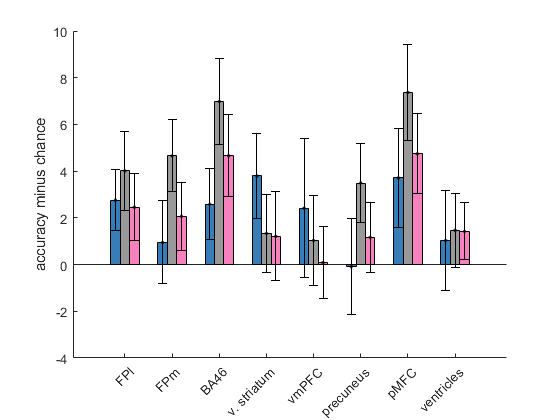

figure; hold on;

b_YN = bar(-1:10:69,nanmean(YN,2),'BarWidth',0.2, 'FaceColor',cb(2,:));
errorbar(-1:10:69,nanmean(YN,2),nanstd(YN')/sqrt(29),'.k')
b_dis_cross_det = bar(1:10:71,nanmean(dis_cross_det,2),'BarWidth',0.2, 'FaceColor',cb(10,:));
b_dis_cross_det.FaceColor = 'flat';

errorbar(1:10:71,nanmean(dis_cross_det'), nanstd(dis_cross_det')/sqrt(29), '.k');

b_dis_cross_YN = bar(3:10:73,nanmean(dis_cross_YN,2),'BarWidth',0.2, 'FaceColor',cb(9,:));
b_dis_cross_YN.FaceColor = 'flat';

errorbar(3:10:73,nanmean(dis_cross_YN'), nanstd(dis_cross_YN')/sqrt(29), '.k');

xticks(1:10:71);
xticklabels({'FPl','FPm','BA46','v. striatum',...
    'vmPFC','precuneus','pMFC','ventricles'});
xtickangle(45);
ylabel('accuracy minus chance')

fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png'; 
s.Width = 25;
s.Height = 12;
hgexport(fig,'figures/confidence_cross_resp',s);